close all

% number of nodes
N=10;

% Adjacency matrix
A=[ 0 1 1 0 0 0 0 0 1 1;
    1 0 1 1 0 0 0 0 0 1;
    1 1 0 1 1 0 0 0 0 0;
    0 1 1 0 1 1 0 0 0 0; 
    0 0 1 1 0 1 1 0 0 0;
    0 0 0 1 1 0 1 1 0 0;
    0 0 0 0 1 1 0 1 1 0;
    0 0 0 0 0 1 1 0 1 1;
    1 0 0 0 0 0 1 1 0 1;
    1 1 0 0 0 0 0 1 1 0] ;
G= graph(A)

G =   graph with properties:

    Edges: [20×2 table]
    Nodes: [10×0 table]


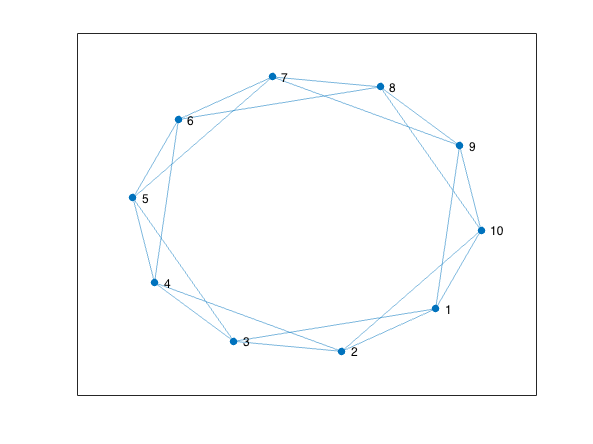

plot(G)

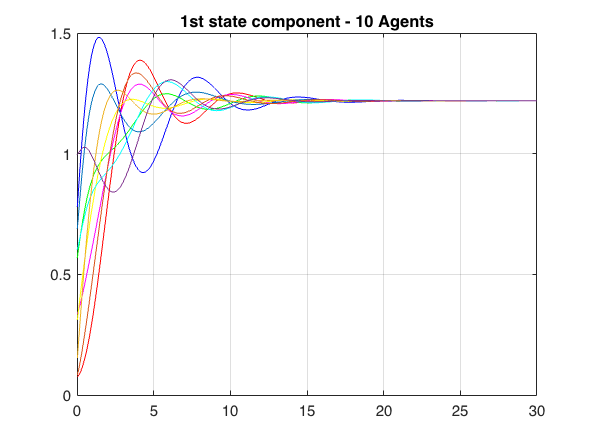


% Laplacian matrix of graph(G)
L = laplacian(G);

%Agent initial position (random)
x0=rand(3*N,1);

%% system

I=eye(N);
Y=I;
%E1=[ 0 1 0; 0 0 1; 0 -2 -3];
E2=[ 0 1 0; 0 0 1; 0 -4 -6];
F=[ 0 0 0; 0 0 0; 1 0 0 ];
 
O=(kron(I,E2))-(kron((Y*L),F));
V=ones(3*N,1);
W=eye(3*N);
X=0;
sys=ss(O,V,W,X);

t = 0:0.01:30;
%u = max(0,min(t-1,1));
u=zeros(size(t));
 
[y,t,x]=lsim(sys, u, t, x0);

%% plot
figure;
plot(t,y(:,1),'r');
hold on
plot(t,y(:,4),'b');
plot(t,y(:,7),'g');
plot(t,y(:,10),'m');
plot(t,y(:,13),'y');
plot(t,y(:,16),'c');
plot(t,y(:,19),'color','#0072BD');
plot(t,y(:,22),'color','#D95319');
plot(t,y(:,25),'color','#EDB120');
plot(t,y(:,28),'color','#7E2F8E');
grid on
title('1st state component - 10 Agents')
hold off

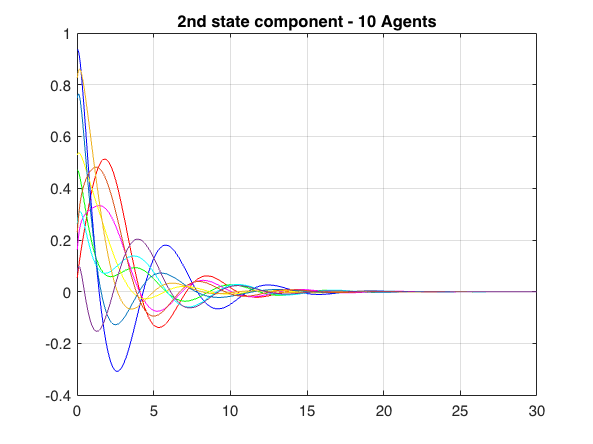

 
figure;
plot(t,y(:,2),'r');
hold on
plot(t,y(:,5),'b');
plot(t,y(:,8),'g');
plot(t,y(:,11),'m');
plot(t,y(:,14),'y');
plot(t,y(:,17),'c');
plot(t,y(:,20),'color','#0072BD');
plot(t,y(:,23),'color','#D95319');
plot(t,y(:,26),'color','#EDB120');
plot(t,y(:,29),'color','#7E2F8E');
grid on
title('2nd state component - 10 Agents')
hold off

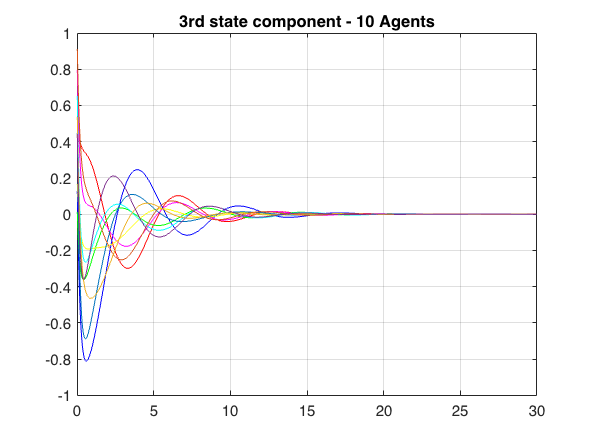

 
figure;
plot(t,y(:,3),'r');
hold on
plot(t,y(:,6),'b');
plot(t,y(:,9),'g');
plot(t,y(:,12),'m');
plot(t,y(:,15),'y');
plot(t,y(:,18),'c');
plot(t,y(:,21),'color','#0072BD');
plot(t,y(:,24),'color','#D95319');
plot(t,y(:,27),'color','#EDB120');
plot(t,y(:,30),'color','#7E2F8E');
grid on
title('3rd state component - 10 Agents')
hold off